# ************************************************

Example 3D-FDTD code to simulate scattering

v1.0 - July 2015

Jonathan Sheaffer, Ben-Gurion University, Israel Trevor Cox, University of Salford, UK

clear
close
clc

## ************************************************

DEFINE SIMULATION PARAMETERS

roomDims = [3,3,2]        % Room dimensions [Lx, Ly, Lz] in meters

roomDims =      3     3     2


srcPos = [2,1,1]        % Source position [x,y,z] in meters

srcPos =      2     1     1



recPos = [srcPos(1),srcPos(2)+1,srcPos(3)] %Receiver position [x,y,z] in meters

recPos =      2     2     1



fs=100000;                  % Sample rate (Hz)
lam=sqrt(1/3);             % Courant number
c=1480;                   % Speed of sound in water in m/s
simLength = 0.004;          % Simulation length (seconds)
ra = 1e-10;                % Admittance of rigid materials

time = 0.0;                %# Time variable to keep track of the time

T=1/fs                    % (temporal) sample period

T = 1.0000e-05

X=c*T/lam                 % (spatial) sample period

X = 0.0256


maxc = 0.03;               % caxis limits (for visualisation only)

roomDimsD = round(roomDims/X)+2    % Room dimensions [Nx,Ny,Nz] in nodes

roomDimsD =    119   119    80


srcPosD = round(srcPos/X)          % Discrete source position

srcPosD =     78    39    39



recPosD = round(recPos/X)           % Discrete receiver position

recPosD =     78    78    39



maxN = round(simLength/T)

maxN = 400


backscatter = zeros(maxN,1) % Array to store backscatter data 

backscatter =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## ************************************************

DESIGN EXCITATION FUNCTION

We design a simple Gaussian pulse, and pass it through a DC blocking filter (to avoid exciting near zero frequency)

fc = 0.075;     % Cutoff frequency (normalised 0.5=nyquist)
n0 = 30;        % Initial delay (samples)
sigma=sqrt(2*log(2))/(2*pi*(fc/T)) %flow resistivity

sigma = 2.4985e-05

n=0:maxN

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


srcFn=exp(-T^2*(n-n0).^2/(2*sigma^2))

srcFn =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0015    0.0059    0.0198    0.0559    0.1350    0.2776    0.4863    0.7259    0.9230    1.0000    0.9230    0.7259    0.4863    0.2776    0.1350    0.0559    0.0198    0.0059    0.0015    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


srcFn=filter([1 -1], [1 -0.995], srcFn) % DC Blocker

srcFn =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0015    0.0059    0.0197    0.0558    0.1346    0.2765    0.4839    0.7210    0.9145    0.9869    0.9050    0.7033    0.4603    0.2493    0.1054    0.0258   -0.0105   -0.0243   -0.0286   -0.0296   -0.0297   -0.0296   -0.0295   -0.0293   -0.0292   -0.0290   -0.0289   -0.0288   -0.0286


## ************************************************

ALLOCATE MATRICES

p = zeros([roomDimsD 3])   % Pressure matrix (Nx x Ny x Nz x 3)

p = p(:,:,1,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

% Fourth dimension is discrete time
% (:,:,:,1) is (n+1)
% (:,:,:,2) is (n)
% (:,:,:,3) is (n-1)
% Nx is rows, Ny is coloums and Nz is page

K = zeros(roomDimsD)       % Node classification mask

K = K(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

% 6 = air, 5 = surface, 4 = edge, 3 = corner
% All nodes are air by default

beta = ones(roomDimsD)*ra  % Boundary admittance mask

beta = beta(:,:,1) =

   1.0e-10 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

% default is rigid material ("ra")

% Define shift vectors
ll=2:roomDimsD(1)-1

ll =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


mm=2:roomDimsD(2)-1

mm =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


ii=2:roomDimsD(3)-1

ii =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


## ************************************************

DEFINE BOUNDARY CONDITIONS

% Walls - absorptive
%# Setting the 'faces'/walls of the grid as absorptive
K(2,:,:)=5;         beta(2,:,:)=1;      
K(end-1,:,:)=5;     beta(end-1,:,:)=1;
K(:,2,:)=5;         beta(:,2,:)=1;
K(:,end-1,:)=5;     beta(:,end-1,:)=1; 
K(:,:,2)=5;         beta(:,:,2)=1;
K(:,:,end-1)=5;     beta(:,:,end-1)=1;


%# All the middle nodes are set to 'air'
K(3:end-2,3:end-2,3:end-2)=6;

% Scatterer - reflective
%# Setting up the geometrical boxes you see on the left hand side
%# 
K(2:10,30:35,2:end-1)=0;    %# The inside bit
K(2:10,30,2:end-1)=5;       %# The walls
K(2:10,35,2:end-1)=5;       %# The walls
K(10,30:35,2:end-1)=5;      %# The walls
K(2,30:35,2:end-1)=5;       %# The walls
K(10,30,2:end-1)=6;         %# The edges? Like the corners...?
K(10,35,2:end-1)=6;         %# The edges? Like the corners...?

K

K = K(:,:,1) =

     0     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     0
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     

## ************************************************

PREPARE SIMULATION

% Intermediate boundary matrix
BK = (6-K)*lam.*beta/2

BK = BK(:,:,1) =

    0.0000    0.2887    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  


% Find nodes where K has value 0
zero_K=find(K==0)

zero_K =      1
     3
     4
     5
     6
     7
     8
     9
    10
    11


## ************************************************

EXECUTE SIMULATION

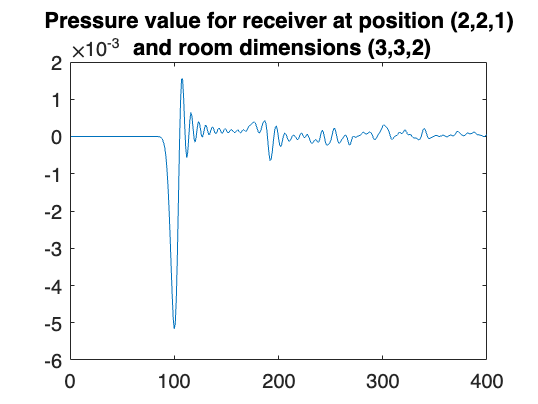

for nn=2:maxN
    
    % Update the grid
    p(ll,mm,ii,1) = ((2-K(ll,mm,ii)*lam^2).*p(ll,mm,ii,2) + (BK(ll,mm,ii)-1).*p(ll,mm,ii,3) ...
        + (lam^2) * (p(ll+1,mm,ii,2) + p(ll-1,mm,ii,2) + p(ll,mm+1,ii,2) ...
        + p(ll,mm-1,ii,2) + p(ll,mm,ii+1,2) + p(ll,mm,ii-1,2))) ./ (1+BK(ll,mm,ii));

    % Enforce zero pressure at 'dead spaces' (inside objects)
    p(zero_K)=0;
    
    % Inject the source (soft source)
    %# Injecting the souce at n
    p(srcPosD(1),srcPosD(2),srcPosD(3),2) = p(srcPosD(1),srcPosD(2),srcPosD(3),2) + srcFn(nn);
    
    % Shift matrices in time
    %# p(n-1) takes the value of p(n) and p(n) takes the value of p(n+1)
    p(:,:,:,3) = p(:,:,:,2);
    p(:,:,:,2) = p(:,:,:,1);

    %save backscatter data into matrix.
    backscatter(nn) = p(recPosD(1),recPosD(2),recPosD(3),2);

end
%plot backscatter data at receiver
figure
plot(backscatter)
title({ ...
    ['Pressure value for receiver at position (' num2str(recPos(1)) ',' num2str(recPos(2)) ',' num2str(recPos(3)) ')'] ...
    [' and room dimensions (' num2str(roomDims(1)) ',' num2str(roomDims(2)) ',' num2str(roomDims(3)) ')'] ...
    })